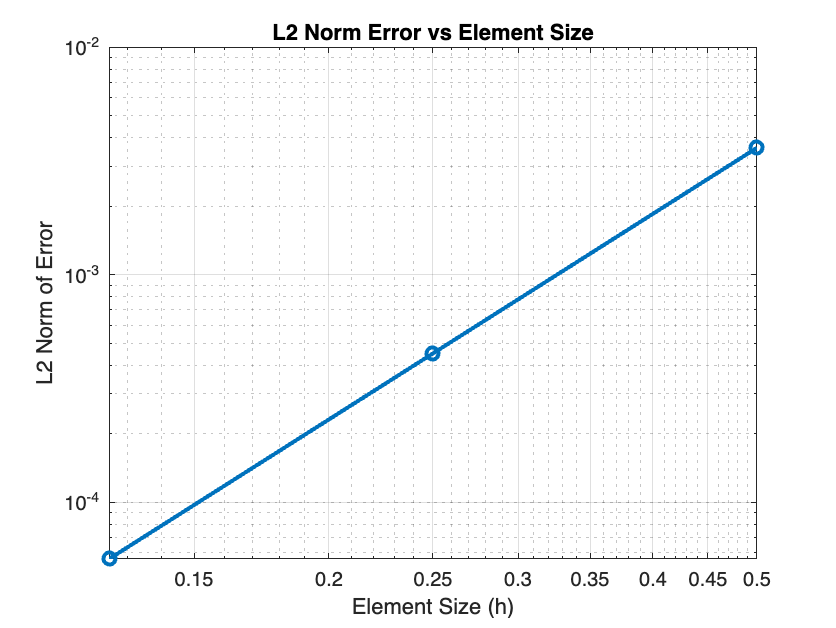

% Define the exact solution u(x) = x^3 as an anonymous function
exact_solution = @(x) x.^3;

% Define the Gauss quadrature points and weights for a 3-point rule (for quadratic element)
gauss_points = [-sqrt(3/5), 0, sqrt(3/5)];  % Gauss points in [-1, 1]
gauss_weights = [5/9, 8/9, 5/9];  % Weights for 3-point quadrature

% Initialize an array to store the L2 norm error for 2, 4, and 8 elements
error_L2 = zeros(3, 1);  % To store errors for each mesh size

% Define the mesh sizes
mesh_sizes = [2, 4, 8];
L = 1;  % Length of the domain

% Loop over each mesh size so that it will run the values for 2, 4, and 8 elements.
for mesh_index = 1:length(mesh_sizes)
    num_elements = mesh_sizes(mesh_index);  % Get the number of elements
    element_length = L / num_elements;  % Compute the length of each element
    error_sum = 0;  % Initialize the error sum for this mesh size

    % Loop over each element
    for elem = 1:num_elements
        % Define element boundaries and the middle node
        x1 = (elem - 1) * element_length;  % Left node of element
        x2 = x1 + element_length / 2;      % Middle node of element
        x3 = elem * element_length;        % Right node of element

        % Quadratic shape function for the element
        u_h = @(x) ((x - x2) * (x - x3)) / ((x1 - x2) * (x1 - x3)) * exact_solution(x1) + ...
                   ((x - x1) * (x - x3)) / ((x2 - x1) * (x2 - x3)) * exact_solution(x2) + ...
                   ((x - x1) * (x - x2)) / ((x3 - x1) * (x3 - x2)) * exact_solution(x3);

        % Compute the squared error for each Gauss point
        for i = 1:length(gauss_points)
            % Map Gauss point to the actual element
            xi = ((x3 - x1) / 2) * gauss_points(i) + (x3 + x1) / 2;

            % Compute the error at the Gauss point
            error_at_gauss_point = (u_h(xi) - exact_solution(xi))^2;

            % Sum the contribution of this Gauss point
            error_sum = error_sum + gauss_weights(i) * error_at_gauss_point * (x3 - x1) / 2;
        end
    end

    % Store the L2 norm error for this mesh size
    error_L2(mesh_index) = sqrt(error_sum);
end

% Plot the error vs element size (log-log plot)
element_sizes = 1 ./ mesh_sizes;  % Element size = 1 / number of elements
figure;
loglog(element_sizes, error_L2, '-o', 'LineWidth', 2);
xlabel('Element Size (h)');
ylabel('L2 Norm of Error');
title('L2 Norm Error vs Element Size');
grid on;


% Optionally, compute the slope of the log-log plot (convergence rate)
p = polyfit(log(element_sizes), log(error_L2), 1);
fprintf('Slope of the log-log plot (rate of convergence): %.2f\n', p(1));

Slope of the log-log plot (rate of convergence): 3.00
